Loaded 20180328 trial

data_temp_1 = data_twoDrives{1,1}; %ECOG
data_temp_2 = data_twoDrives{1,2}; %SC32
data_two_drives = cat(2,data_temp_1,data_temp_2);

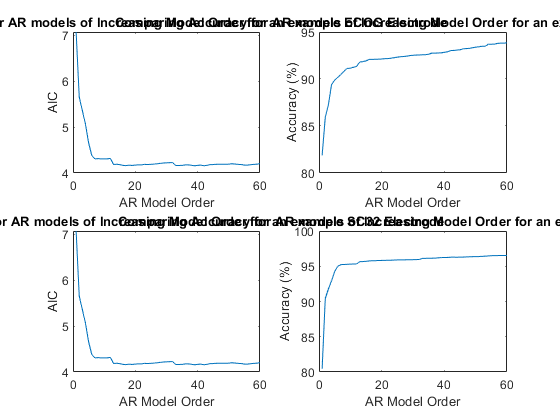

%   select max model order

trial_1 = 1;
electrode_i = 2;

Ts = 0.2; %sampling time
model_order = 60; %from the paper 30

%do this for an ECOG electrode
data_trial = sq(data_twoDrives{1,1}(trial_1,electrode_i,:));
[acc_models_ECOG, model_i, sys_test, aic_models_ECOG] = try_model_orders(model_order, data_trial, Ts);
%do this for an SC32 Electrode

data_trial = sq(data_twoDrives{1,2}(trial_1,electrode_i,:));
[acc_models_SC32, model_i, sys_test, aic_models_SC32] = try_model_orders(model_order, data_trial, Ts);
subplot(2,2,1)
plot(aic_models_SC32)
title('Comparing AIC for AR models of Increasing Model Order for an example ECOG Electrode')
xlabel('AR Model Order')
ylabel('AIC')

subplot(2,2,2)
plot(acc_models_ECOG)
title('Comparing Accuracy for AR models of Increasing Model Order for an example ECOG Electrode')
xlabel('AR Model Order')
ylabel('Accuracy (%)')

subplot(2,2,3)
plot(aic_models_SC32)
title('Comparing AIC for AR models of Increasing Model Order for an example SC32 Electrode')
xlabel('AR Model Order')
ylabel('AIC')

subplot(2,2,4)
plot(acc_models_SC32)
title('Comparing Accuracy for AR models of Increasing Model Order for an example SC32 Electrode')
xlabel('AR Model Order')
ylabel('Accuracy (%)')

This time we got it right. We have substantial reduction in AIC and increase in accuracy as we increase the model order. This is something we expected! 

The concern is that, even at an order 1, we already have an accuracy of around 80%. Why is this does it make sense. We need to compare the models

We can still use AR approach, so now what we are going to do is to get an AR estimates for all electrodes in one run.


trial_1 = 1;
electrode_i = 2;

Ts = 0.2; %sampling time
model_order = 30; %from the paper: 30


electrode_N = size(data_two_drives,2);

acc_models_electrodes = zeros(electrode_N,model_order);
aic_models_electrodes = zeros(electrode_N,model_order);

for electrode_i = 1:electrode_N
    data_trial = sq(data_two_drives(trial_1,electrode_i,:)); %select all electrodes
    
    [acc_models, model_i, sys_test, aic_models] = try_model_orders(model_order, data_trial, Ts);
    
    acc_models_electrodes(electrode_i,:) = acc_models';
    aic_models_electrodes(electrode_i,:) = aic_models';
    
    if mod(electrode_i,10) == 0
        fprintf('Finished: %d electrode\n',electrode_i)
    end
end

Finished: 10 electrode
Finished: 20 electrode
Finished: 30 electrode
Finished: 40 electrode
Finished: 50 electrode
Finished: 60 electrode
Finished: 70 electrode
Finished: 80 electrode
Finished: 90 electrode
Finished: 100 electrode
Finished: 110 electrode
Finished: 120 electrode
Finished: 130 electrode
Finished: 140 electrode
Finished: 150 electrode
Finished: 160 electrode
Finished: 170 electrode
Finished: 180 electrode
Finished: 190 electrode
Finished: 200 electrode
Finished: 210 electrode
Finished: 220 electrode
Finished: 230 electrode
Finished: 240 electrode


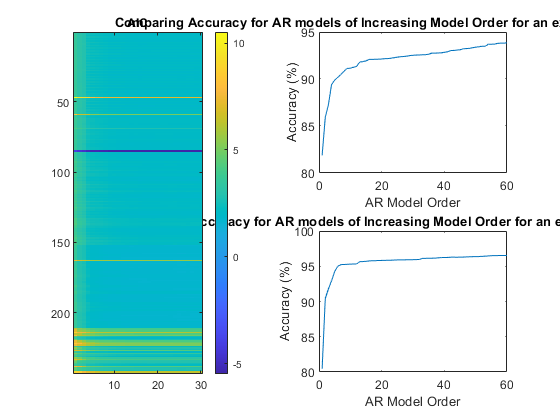

subplot(1,2,1)
imagesc(aic_models_electrodes)
title('AIC')
colorbar

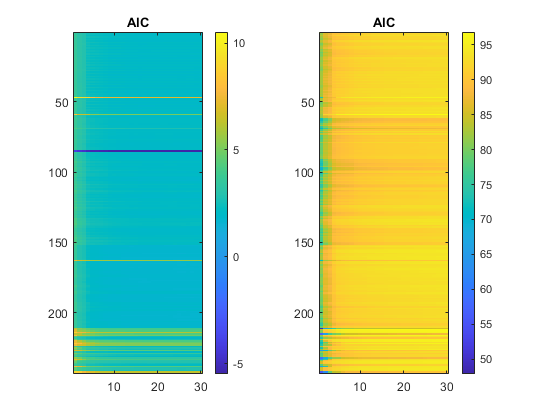


subplot(1,2,2)
imagesc(acc_models_electrodes)
title('AIC')
xlabel('Model Order')
ylabel('Electrodes')
colorbar

Actually from AR modelling, we can identify the outlier electrodes using the AIC infomration criteron.   

We are gonna directly compare the results between different models

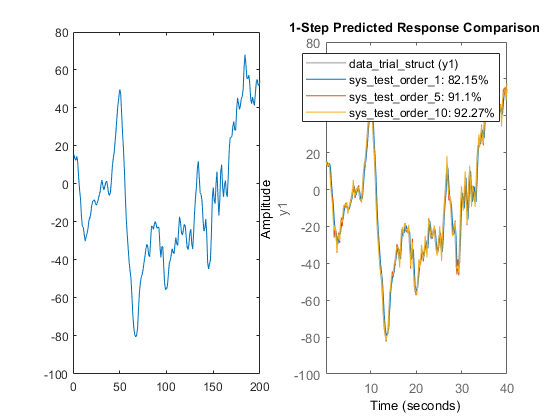

electrode_i = 1;
data_trial = sq(data_two_drives(trial_1,electrode_i,:)); %select all electrodes
data_trial_struct = iddata(data_trial,[],Ts);

model_i = 1;
sys_test_order_1 = ar(data_trial_struct,model_i);

model_i = 5;
sys_test_order_5 = ar(data_trial_struct,model_i);

model_i = 10;
sys_test_order_10 = ar(data_trial_struct,model_i);

figure
subplot(1,2,1)
plot(data_trial)

subplot(1,2,2)
compare(data_trial_struct,sys_test_order_1,sys_test_order_5,sys_test_order_10,1)

After this, we can finally grab the coefficients for graphic modelling

model_i = 14;
trial_1 = 1;
Ts = 0.2;
electrode_N = 211 + 32;
a_coefficients_electrodes = zeros(electrode_N,model_i + 1);

for electrode_i = 1:electrode_N
    data_trial = sq(data_two_drives(trial_1,electrode_i,:)); %select all electrodes
    data_trial_struct = iddata(data_trial,[],Ts);
    
    sys_test = ar(data_trial_struct,model_i);
    a_coefficients_electrodes(electrode_i,:) = sys_test.A;
    
    if mod(electrode_i,10) == 0
        fprintf('Finished: %d electrode\n',electrode_i)
    end
end

Finished: 10 electrode
Finished: 20 electrode
Finished: 30 electrode
Finished: 40 electrode
Finished: 50 electrode
Finished: 60 electrode
Finished: 70 electrode
Finished: 80 electrode
Finished: 90 electrode
Finished: 100 electrode
Finished: 110 electrode
Finished: 120 electrode
Finished: 130 electrode
Finished: 140 electrode
Finished: 150 electrode
Finished: 160 electrode
Finished: 170 electrode
Finished: 180 electrode
Finished: 190 electrode
Finished: 200 electrode
Finished: 210 electrode
Finished: 220 electrode
Finished: 230 electrode
Finished: 240 electrode


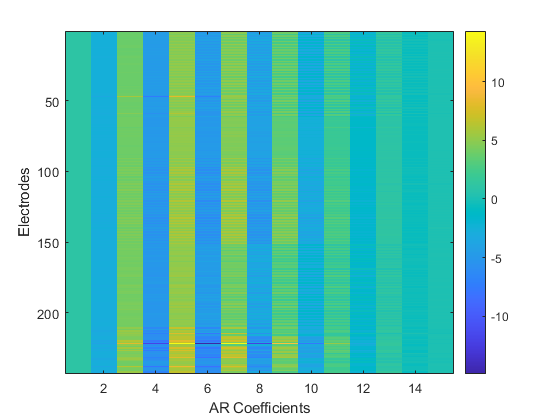

imagesc(a_coefficients_electrodes)
colorbar
xlabel('AR Coefficients')
ylabel('Electrodes')

This figure basically shows that  the positive and negative coeffs of the AR model with 14 coefficients.

now a_coefficients_electrodes is our feature matrix which we will use to find the L matrix by optimization. 

function [acc_models, model_i, sys_test, aic_models] = try_model_orders(model_order, data_trial, Ts)
data_trial_struct = iddata(data_trial,[],Ts);


aic_models = zeros(model_order,1);
acc_models = zeros(model_order,1);

for model_i = 1:model_order
    %fit to the model
    sys_test = ar(data_trial_struct,model_i);
    
    %save AIC
    aic_models(model_i) = aic(sys_test);
    
    %save accuracy
    acc_models(model_i) = sys_test.Report.Fit.FitPercent;
    
%     if mod(model_i,10) == 0
%         fprintf('Finished: %d models\n',model_i)
%     end
end
end